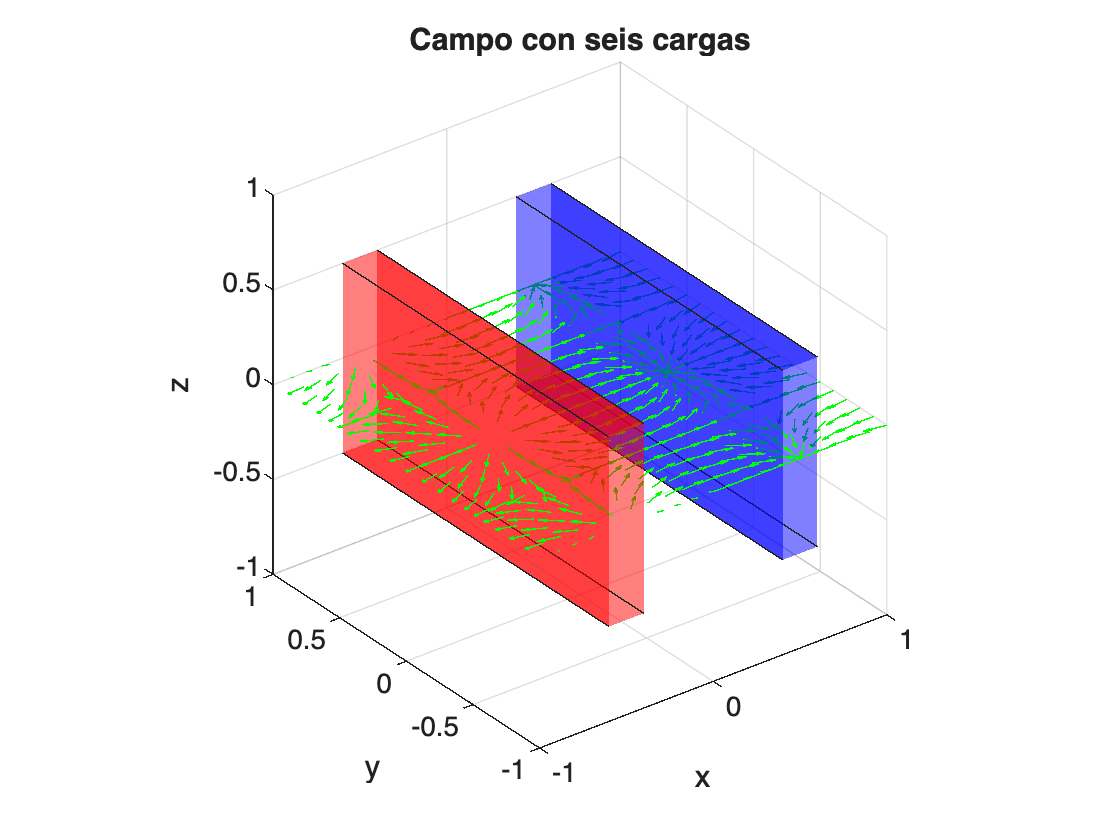

q1 = 1;
q2 = -1;
q3 = 1;
q4 = -1;
q5 = 1;
q6 = -1;
d = 0.5;
[x, y] = meshgrid(-1:0.1:1, -1:0.1:1); 
z = zeros(size(x));

x1 = -d; y1 = -1;
x2 = d;  y2 = -1;
x3 = -d; y3 = 0;
x4 = d;  y4 = 0;
x5 = -d; y5 = 1;
x6 = d;  y6 = 1;

% ------- q1 -------
rx1 = x - x1;
ry1 = y - y1;
r1 = sqrt((rx1.^2) + (ry1.^2));

% -> E1
ex1 = (q1./(r1.^3)) .* rx1;
ey1 = (q1./(r1.^3)) .* ry1;

% ------- q2 -------
rx2 = x - x2;
ry2 = y - y2;
r2 = sqrt((rx2.^2) + (ry2.^2));

% -> E2
ex2 = q2./(r2.^3) .* rx2;
ey2 = q2./(r2.^3) .* ry2;

% ------- q3 -------
rx3 = x - x3;
ry3 = y - y3;
r3 = sqrt((rx3.^2) + (ry3.^2));

% -> E3
ex3 = q3./(r3.^3) .* rx3;
ey3 = q3./(r3.^3) .* ry3;

% ------- q4 -------
rx4 = x - x4;
ry4 = y - y4;
r4 = sqrt((rx4.^2) + (ry4.^2));

% -> E4
ex4 = q4./(r4.^3) .* rx4;
ey4 = q4./(r4.^3) .* ry4;

% ------- q5 -------
rx5 = x - x5;
ry5 = y - y5;
r5 = sqrt((rx5.^2) + (ry5.^2));

% -> E5
ex5 = q5./(r5.^3) .* rx5;
ey5 = q5./(r5.^3) .* ry5;

% ------- q6 -------
rx6 = x - x6;
ry6 = y - y6;
r6 = sqrt((rx6.^2) + (ry6.^2));

% -> E6
ex6 = q6./(r6.^3) .* rx6;
ey6 = q6./(r6.^3) .* ry6;

% ------- Campo Electrico Final -------

ex = ex1 + ex2 + ex3 + ex4 + ex5 + ex6;
ey = ey1 + ey2 + ey3 + ey4 + ey5 + ey6;
ez = zeros(size(ex));


% ------- Magnitudes del campo electrico -------

em = sqrt((ex.^2)+(ey.^2)+(ez.^2));

% ------- Campo Electrico Normalizado -------

exn = ex./em;
eyn = ey./em;
ezn = zeros(size(exn));


% ------- QUIVER -------
figure 
hold on
axis equal
view(3)
axis([-1 1 -1 1 -1 1])
grid on
quiver3(x, y, z, exn, eyn, ezn, 'g') 
title('Campo con seis cargas')
xlabel('x')
ylabel('y')
zlabel('z')


v = 0.5;

function vertices = crear_prisma(xc, yc, zc, ancho, largo, v)

    vertices = [
        -v*ancho+xc, -v*largo+yc, -v+zc;
        -v*ancho+xc,  v*largo+yc, -v+zc;
         v*ancho+xc,  v*largo+yc, -v+zc;
         v*ancho+xc, -v*largo+yc, -v+zc;
        -v*ancho+xc, -v*largo+yc,  v+zc;
        -v*ancho+xc,  v*largo+yc,  v+zc;
         v*ancho+xc,  v*largo+yc,  v+zc;
         v*ancho+xc, -v*largo+yc,  v+zc];
end 


% desplazamiento global
dx= -0.5;
dy = 0;
dz = 0;

% dimensiones de placas 
largo_roja = 3;
largo_azul = 3;
ancho = -0.2;


% posiciones de las placas en x 
x_roja = -d;
x_azul = d;


%caras de la caja 
caras = [1 2 3 4;
         2 6 7 3;
         4 3 7 8;
         1 5 8 4;
         1 2 6 5;
         5 6 7 8];

% placa roja 
vertices_roja = crear_prisma(x_roja, dy, dz, ancho, largo_roja, v);
% placa azul 
vertices_azul = crear_prisma(x_azul, dy, dz, ancho, largo_azul, v);

% dibujar placas
patch('Faces', caras,'Vertices', vertices_roja,'FaceColor','r','FaceAlpha',0.5);
patch('Faces', caras,'Vertices', vertices_azul,'FaceColor','b','FaceAlpha',0.5);